close all
clear
clc

定义初始状态和仿真时间范围

s0 = [-4.2E7;0;0;4000];
tspan = [0,60*60*24*60];

仿真卫星运动

[t,st] = ode23('myodefun',tspan,s0);

取状态的前两维为卫星运动的x、y坐标并绘图

xt = st(:,1);
yt = st(:,2);
figure, hold on, box on;
plot(xt,yt,'k');

绘制地球做参照

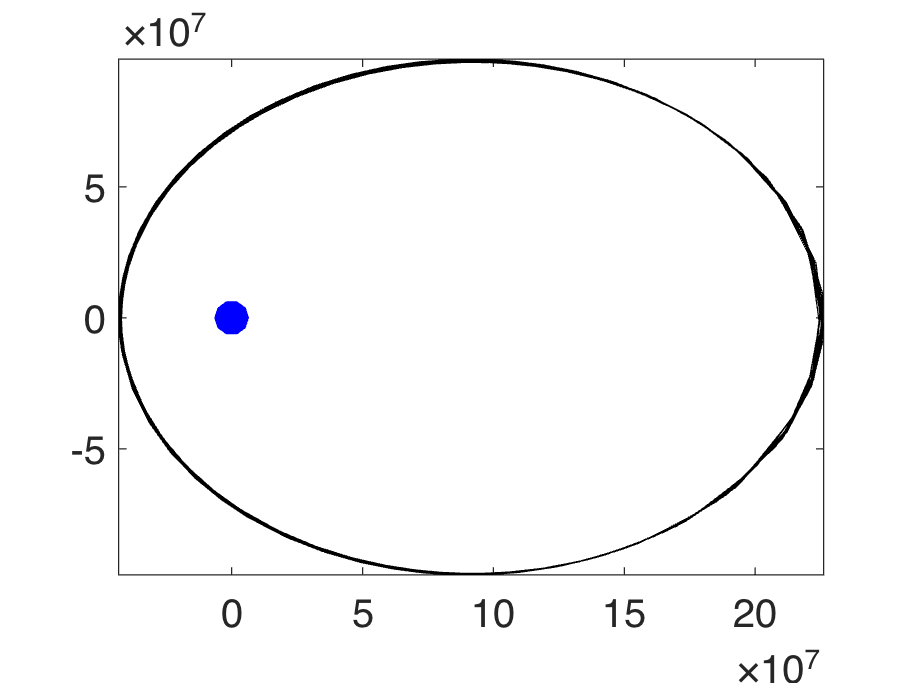

[XE,YE,ZE] = sphere(10);
RE = 6.378E6;
colormap([0,0,1]);
h = surf(RE*XE,RE*YE,0*ZE);
set(h,'EdgeColor',[0,0,1]);
axis('image');
set(gca,'FontSize',16);

定义描写卫星运动的微分方程

function ds = myodefun(t,s)
G = 6.672E-11;
ME = 5.97E24;

xy = s(1:2);
vxvy = s(3:4);
r = sqrt(xy'*xy);
ds = [vxvy;-G*ME*xy/r^3];
end